n=3; % data dimension
k=10; % number of matrices
p=3; % size of factorization
r=3; % rank of data
A = data(n,k,r);
prob=nonconvex_problem(data(n,k,r),p);

prob = struct with fields:
        n: 3
        k: 10
        p: 3
        A: [3×3×10 double]
        Y: [3×3×10 double]
     cost: @(X)cost(problem.Y,X.E,X.O)
        M: [1×1 struct]
    egrad: @(X)egrad(problem.Y,X.E,X.O)


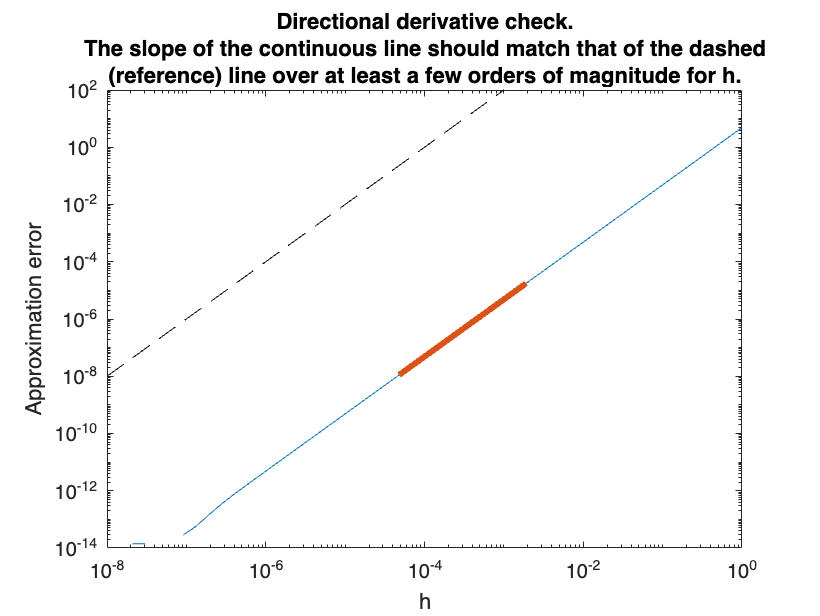

The slope should be 2. It appears to be: 2.
If it is far from 2, then directional derivatives might be erroneous.


checkdiff(prob);

[x, xcost, info, options] = trustregions(prob);

           iter                  cost val     grad. norm    numinner     hessvec   numstored   stopreason
              0   +1.2477241682497328e+02   6.233653e+01
acc TR+       1   +8.2436625761545841e+01   4.614414e+01           1           1           1   exceeded trust region
acc TR+       2   +3.5620869860838354e+01   1.406112e+01           1           1           1   exceeded trust region
acc TR+       3   +2.1926228301396208e+01   1.030849e+01           2           2           2   negative curvature
acc TR-       4   +1.5903204191211357e+01   1.855070e+01           2           2           2   negative curvature
acc           5   +6.0294434705720237e+00   1.469594e+00           2           2           2   reached target residual-kappa (linear)
acc TR+       6   +5.6846243723602710e+00   1.757789e+00           5           5           3   exceeded trust region
acc TR-       7   +5.6162047041715280e+00   2.522821e+00           5           5           4   exceeded trust region
acc TR+

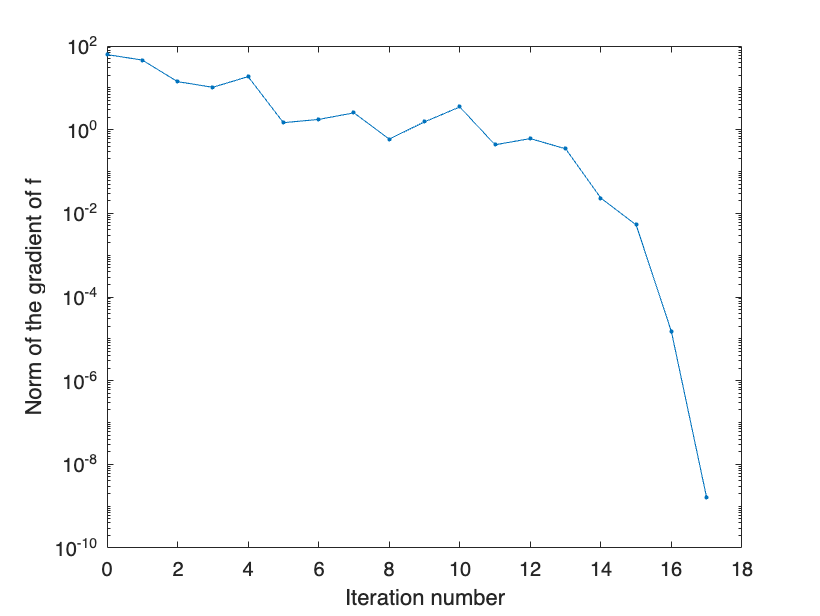

figure;
semilogy([info.iter], [info.gradnorm], '.-');
xlabel('Iteration number');
ylabel('Norm of the gradient of f');